# 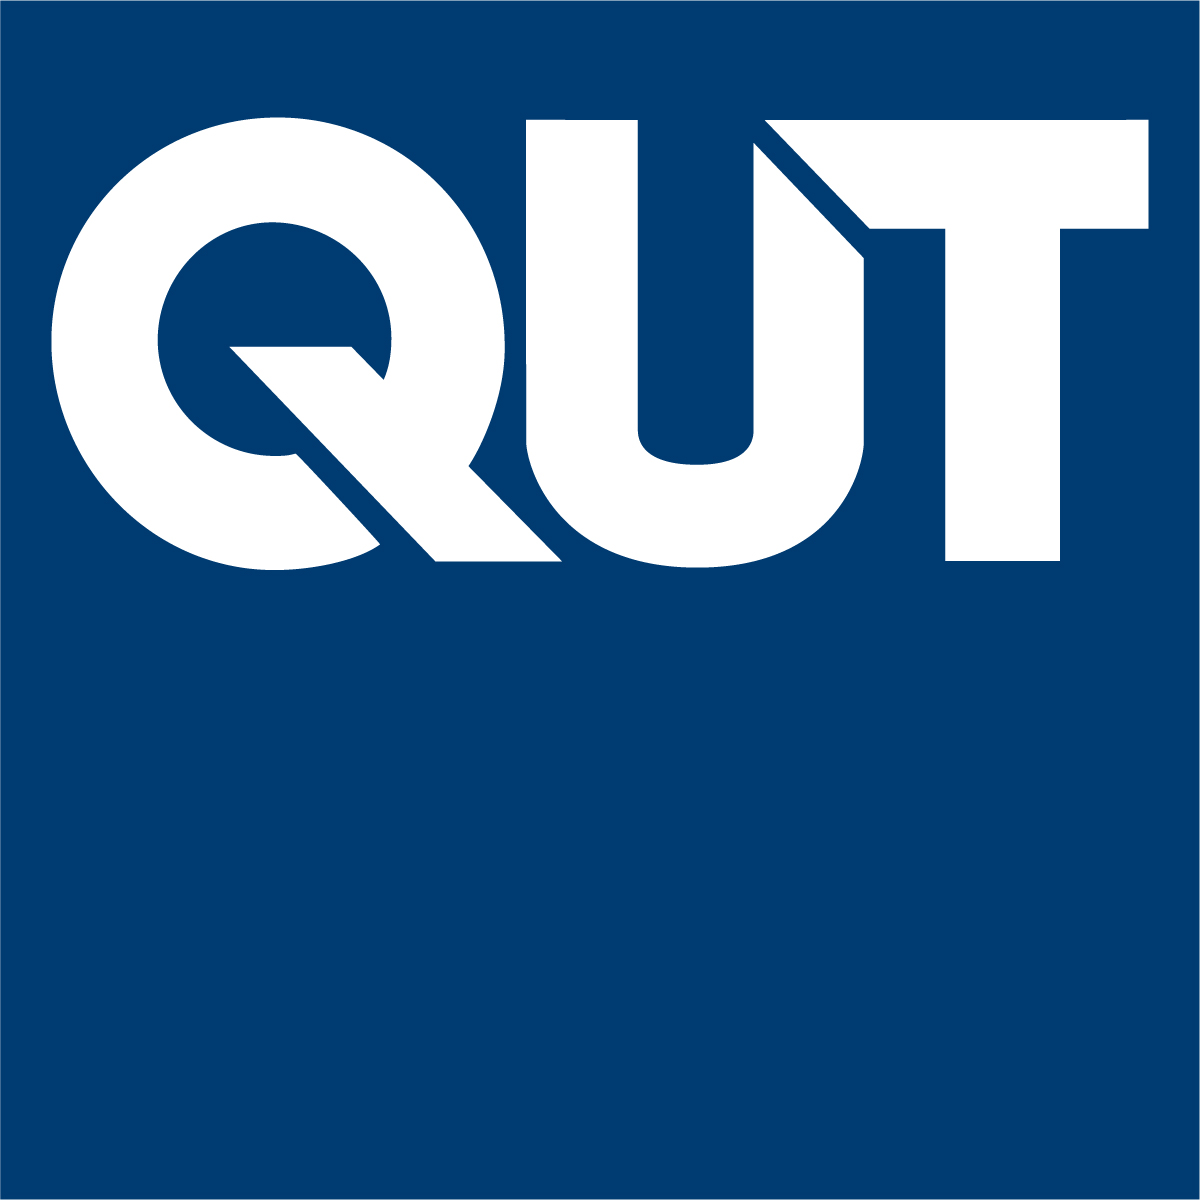

# MXB201 Chapter 4: Eigenvalues and Eigenvectors

Professor Tim Moroney,  2022

V1.0

## 4.1 Introduction

[Video](https://web.microsoftstream.com/video/b1121006-5c76-47ac-bcf8-44c995fa0b27)

In this chapter we make the switch from studying $Ax = b$, to studying the other big equation in linear algebra: $Ax = \lambda x$.  This is the **eigenvalue problem**, and it only makes sense for square matrices $A \in \mathbb{R}^{n \times n}$ (why?).  The problem asks to find any special vectors $x$, particular to the matrix $A$, such that multiplication by $A$ simply *scales the vector* by some factor which we call $\lambda$.  The special vector $x$ is called an *eigenvector* and the corresponding factor $\lambda$ is called the *eigenvalue*.

The eigenvalue problem is of central importance in linear algebra.  Its importance derives from the fact that the eigenvectors *diagonalise* a matrix.  We will gain an appreciation for the power of diagonalisation in this chapter.

Similar to our approach in Chapter 1 on linear systems, this chapter will be built around a number of illustrative examples.

sympref('AbbreviateOutput', false);  % disable automatic substitutions sigma1, sigma2, etc.

## 4.2 Example 1

### The visual picture

[Video](https://web.microsoftstream.com/video/31d4d8b9-5364-40bf-8aa7-3fa5bef473b6)

A = sym([1 -1/5 ; -4/5 1])   % our example 2x2 matrix

$$A = \left(\begin{array}{cc} 1 & -\frac{1}{5}\\ -\frac{4}{5} & 1 \end{array}\right)$$

Observe that in the equation $Ax = \lambda x$, we are free to scale $x$ on both sides by an arbitrary factor $c$, and the equation $A(cx) = \lambda(cx)$ remains true.  Hence, eigenvectors are only unique (at most) up to a multiplicative constant (sometimes we are even free to take linear combinations of eigenvectors -- we will refine this understanding later in the chapter).

It follows that we can get a quick visual understanding of eigenvectors in $\mathbb{R}^2$ by looking at an animation of what multiplication by $A$ does to *unit *vectors $x$.  That is, vectors $x$ with $||x|| = 1$.  That is, vectors $x$ on the unit circle:

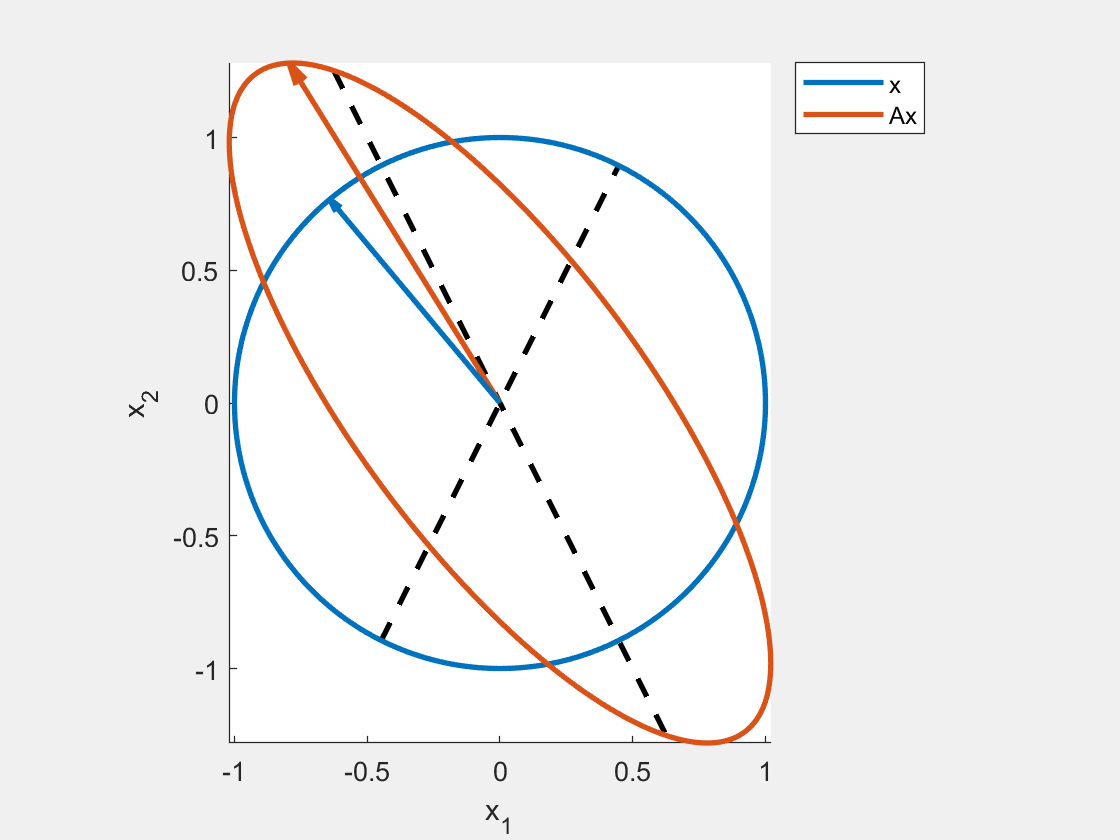

animate_matrix(A, 'e') % animation #1

Interestingly, as we let $x$ roam around the unit circle (blue), we notice that $Ax$ traces out an *ellipse* (red).  Why this should be the case (why an ellipse, and not some other shape?) is not obvious at all, and I'm afraid it will remain a mystery until we learn some more remarkable facts about matrices in the next chapter.  But all the same, what we can observe is that at certain times the vectors $x$ (blue) and $Ax$ (red) align.  These correspond to the eigenvectors of $A$, and their locations are also shown by black dotted lines in the still image above.

A rough sense of the magnitude of the eigenvalues is also deducible from the animation.  When the red ellipse lies within the unit circle at an eigenvector, the corresponding eigenvalue is less than one in magnitude: multiplication by $A$ scales down the length of the vector.  When the red ellipse lies beyond the unit circle at an eigenvector, the corresponding eigenvalue is greater than one in magnitude: multiplication by $A$ scales up the length of the vector.

Eigenvalues can, of course, be positive, negative or zero.  The eigenvalues of the matrix above were both positive.  This too, is clear from the animation: the vectors $x$ and $Ax$ point in the same direction at the eigenvectors (positive eigenvalue), rather than pointing in opposite directions (negative eigenvalue).

### Calculating eigenvalues

[Anton 5.1]

[Video](https://web.microsoftstream.com/video/6f602938-c11d-4dbe-84c9-d61782198de3)

We have deduced much about the eigenvalues and eigenvectors of this matrix $A$ graphically.  Let's now calculate precise numerical values.  We can rearrange the eigenvalue equation $Ax = \lambda x$, into a form suitable for us to analyse using the tools we have developed in previous chapters.  Since $\lambda x = \lambda I x$ where $I$ is the identity matrix, we can write


$$Ax = \lambda x$$



$$Ax = \lambda I x$$



$$\lambda I x - Ax = 0$$



$$(\lambda I - A)x = 0$$


We know from our work in Chapter 1 that this homogeneous linear system $(\lambda I - A)x = 0$ will have *non-trivial *solutions only when the rank of the coefficient matrix $\lambda I - A$is less than $n$.

Since $A$ and $I$ are square matrices, we could equally say that the homogeneous linear system $(\lambda I - A)x = 0$  will have non-trivial solutions only when the coefficient matrix $\lambda I - A$ is *singular*.

Equivalently, the homogeneous linear system $(\lambda I - A)x = 0$  will have non-trivial solutions only when the *determinant *of the matrix $\lambda I - A$ is zero.

This is the most convenient characterisation to use when calculating eigenvalues analytically:

$\det(\lambda I - A) = 0 \iff \lambda$* is an ****eigenvalue**** of *$A$

So the first step in calculating eigenvalues analytically is solving the equation $\det(\lambda I - A) = 0$ to find the eigenvalues $\lambda$.

[Video](https://web.microsoftstream.com/video/c25751ea-3b14-414c-8681-8d6f9f624a66)

#### Exercise

On a piece of paper, go through this same process of finding the characteristic polynomial, and thus the eigenvalues, yourself by hand.  Don't refer to back to the example video or lecture notes unless you really get stuck.▫

We'll use the variable `H` in MATLAB for the matrix $\lambda I - A$ but there's no particular standard notation for this matrix.

syms lambda; I = sym(eye(2));
H = lambda*I - A

$$H = \left(\begin{array}{cc} \lambda -1 & \frac{1}{5}\\ \frac{4}{5} & \lambda -1 \end{array}\right)$$

It's clear from the method of cofactor expansion for calculating determinants that $\det(\lambda I - A) $ will be a *polynomial* in $\lambda$ of degree $n$.  We will call this polynomial $P(\lambda)$, and this is standard notation.  It's called the **characteristic polynomial** of $A$.  Note that it is a *monic *polynomial, i.e. the coefficient of the highest degree term is 1.

*The monic polynomial defined by *$P(\lambda) = \det(\lambda I - A)$* is called the ****characteristic polynomial ****of *$A$*.  Its roots are the eigenvalues of *$A$*.*

P = det(H)

$$P = \lambda^{2}-2\,\lambda +\frac{21}{25}$$

The eigenvalues $\lambda_1$ and $\lambda_2$ are the two roots of this characteristic polynomial.  Since we already used the symbol `lambda` as the variable in the characteristic polynomial, we will need a new symbol in MATLAB for the numerical eigenvalues.  We'll use `d` (a choice made for reasons that will be more apparent later on).

d = solve(P == 0)  % find the roots of the polynomial P

$$d = \left(\begin{array}{c} \frac{3}{5}\\ \frac{7}{5} \end{array}\right)$$

The eigenvalues are thus $\lambda_1 = 3/5$ and $\lambda_2 = 7/5$.  These values accord with all the observations we made visually for this matrix: they are positive, one of which is less than 1, and one of which is greater than one.

#### Exercise

In a (separate) MATLAB editor tab, find the characteristic polynomial, and thus the eigenvalues, yourself.  Don't refer to back to the example code unless you really get stuck.▫

### Calculating eigenvectors

[Video](https://web.microsoftstream.com/video/a8e9efab-5bf0-41b1-9cd6-5d28694067c1)

#### Exercise

On a piece of paper, go through this same process of finding the eigenvectors yourself by hand.  Don't refer to back to the example video or lecture notes unless you really get stuck.▫

Now, as for the eigenvectors, it remains to actually solve the homogeneous linear systems $(\lambda I - A)x = 0$ for $\lambda = \lambda_1$ and $\lambda = \lambda_2$.

H1 = subs(H, d(1))  % substitute lambda = d(1) into lambda*I - A

$$H1 = \left(\begin{array}{cc} -\frac{2}{5} & \frac{1}{5}\\ \frac{4}{5} & -\frac{2}{5} \end{array}\right)$$

By definition, the nontrivial solutions to $(\lambda_1 I - A) x = 0$ form the null space of $\lambda_1 I - A$.  So really, our job is just to find the null space of $\lambda_1 I - A$.  We call this null space the **eigenspace** of $A$ associated with the eigenvalue $\lambda_1$.

v1 = null(H1)

$$v1 = \left(\begin{array}{c} \frac{1}{2}\\ 1 \end{array}\right)$$

As always, the `null` command returns a basis for the null space, which in this case is the single vector $v_1 = \left[\matrix{1/2 \cr 1}\right]$.  Hence $v_1$ is the *eigenvector *corresponding to the eigenvalue $\lambda_1 = 3/5$.  

Bonus points for remembering that any multiple of $v_1$ is also an eigenvector!  In the animation earlier, we saw the *normalised *eigenvector $\hat{v}_1 = v_1 / \|v_1\|$

v1hat = v1 / norm(v1)

$$v1hat = \left(\begin{array}{c} \frac{\sqrt{5}}{5}\\ \frac{2\,\sqrt{5}}{5} \end{array}\right)$$

Here it is, as a still image.

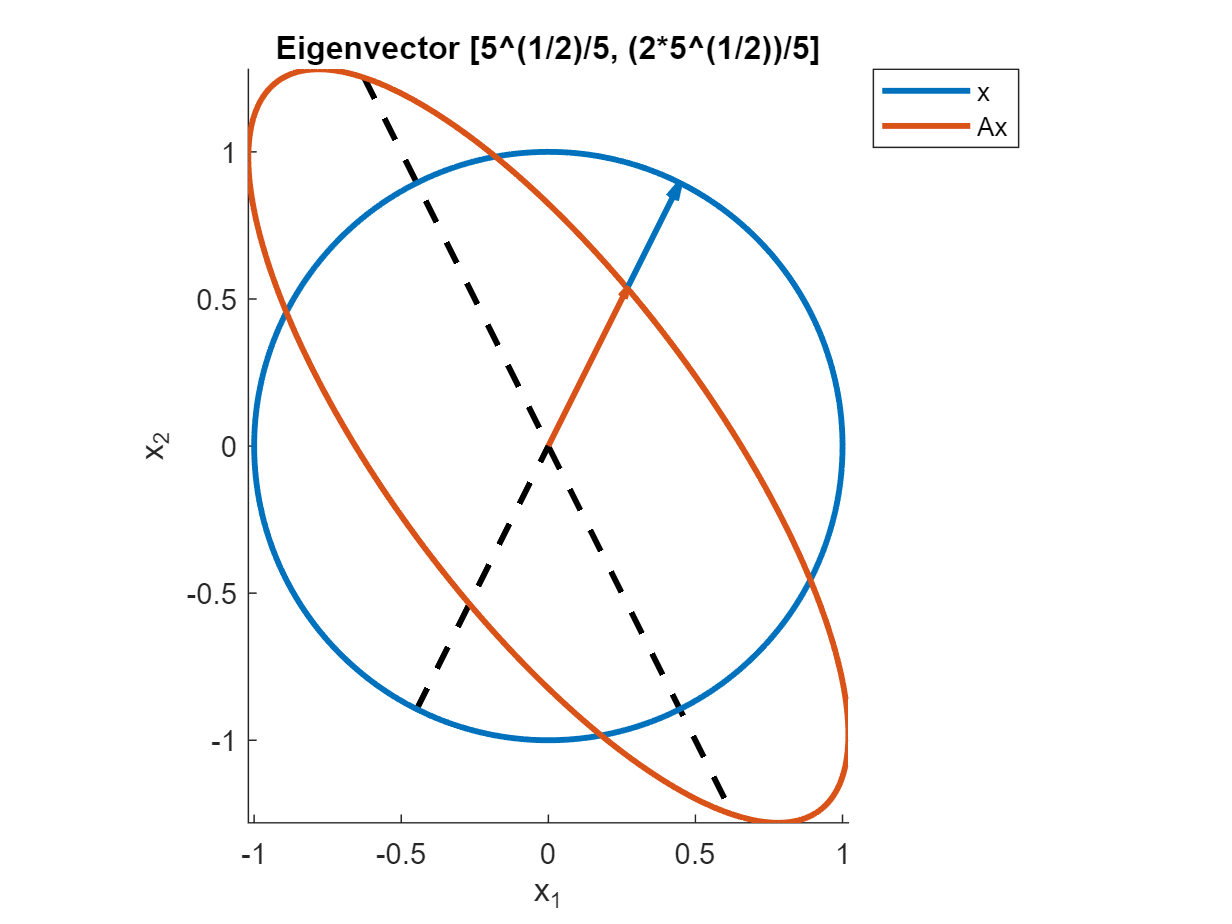

animate_matrix(A, 'e', v1hat)
title("Eigenvector [" + join(string(v1hat'), ", ") + "]", 'Interpreter',"none")

Double bonus points for noticing that we could also see $-\hat{v}_1$ on this image.

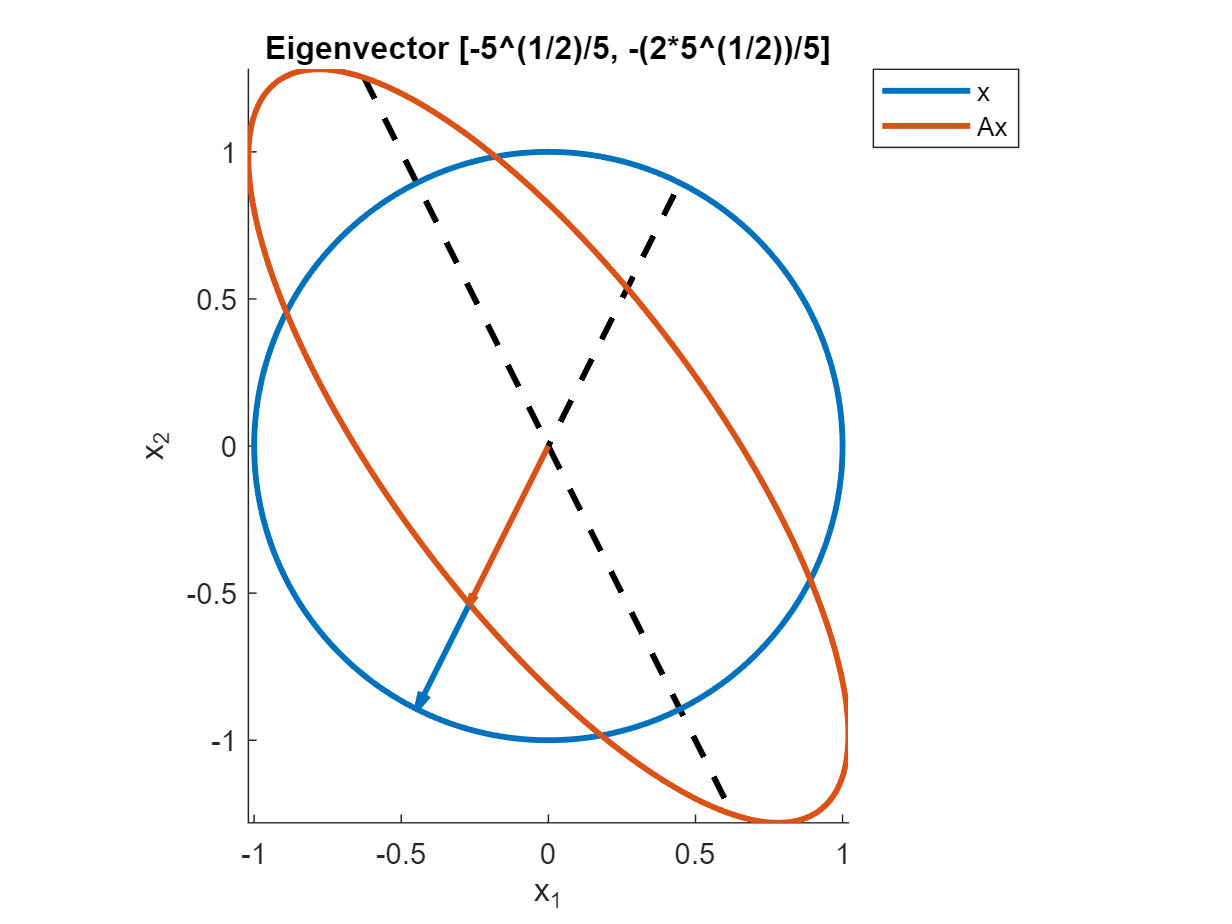

animate_matrix(A, 'e', -v1hat)
title("Eigenvector [" + join(string(-v1hat'), ", ") + "]", 'Interpreter',"none")

Similarly, we can find the eigenvector $v_2$ corresponding to the eigenvalue $\lambda_2 = 7/5$.

H2 = subs(H, d(2))  % substitute lambda = d(2) into lambda*I - A

$$H2 = \left(\begin{array}{cc} \frac{2}{5} & \frac{1}{5}\\ \frac{4}{5} & \frac{2}{5} \end{array}\right)$$

v2 = null(H2)

$$v2 = \left(\begin{array}{c} -\frac{1}{2}\\ 1 \end{array}\right)$$

The second eigenvector is $v_2 = \left[\matrix{-1/2 \cr 1}\right]$.

Here is the normalised version $\hat{v}_2$ shown on the figure.

v2hat = v2 / norm(v2)

$$v2hat = \left(\begin{array}{c} -\frac{\sqrt{5}}{5}\\ \frac{2\,\sqrt{5}}{5} \end{array}\right)$$

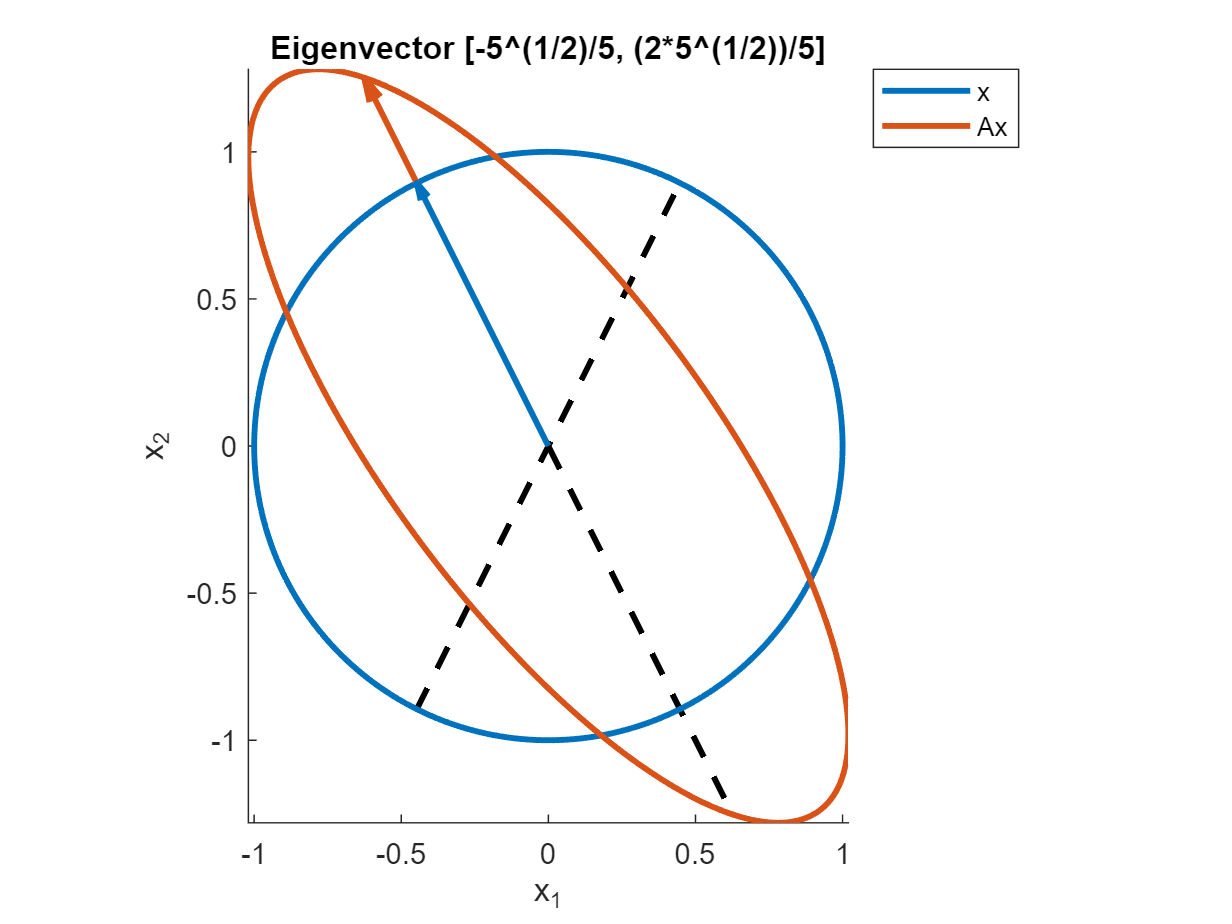

animate_matrix(A, 'e', v2hat)
title("Eigenvector [" + join(string(v2hat'), ", ") + "]", 'Interpreter',"none")

Clearly we could plot $-\hat{v}_2$ as well, if we wanted.  We'll leave that as an exercise for the reader.

#### Exercise

In a (separate) MATLAB editor tab, find the eigenvectors yourself.  Don't refer to back to the example code unless you really get stuck.▫

### Using built-in MATLAB

How do we get MATLAB to compute eigenvalues and eigenvectors for us?  If it's just eigenvalues you want, it couldn't be easier:

eig(A)  % calculate the eigenvalues of A

$$ans = \left(\begin{array}{c} \frac{3}{5}\\ \frac{7}{5} \end{array}\right)$$

The eigenvalues are returned in a vector.  We confirm that MATLAB's answer agrees with our own:

isequal(ans, d)

ans = logical
   1


Note that the order in which the eigenvalues were returned could have been different: MATLAB might have returned the eigenvalues in the reverse order.  But by chance, it chose the same order as us.

What if you also want eigen*vectors*?  In that case, you request two outputs from `eig`:

[V,D] = eig(A) % V is eigenvectors, D is eigenvalues

$$V = \left(\begin{array}{cc} \frac{1}{2} & -\frac{1}{2}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} \frac{3}{5} & 0\\ 0 & \frac{7}{5} \end{array}\right)$$

Now things look quite different.  First, the eigenvectors are the *first *output returned, and the eigenvalues come second.  Second, the eigenvalues have changed from being returned as a vector, to being returned as a diagonal matrix $D$ for some reason!  (The eigenvectors are, unsurprisingly, returned as columns of a matrix, which we called $V$.)

### Matrix diagonalisation

[Anton 5.2]

[Video](https://web.microsoftstream.com/video/32ccb5d6-d9e9-4b04-9855-cbebbaffa3bb)

Why did MATLAB choose this wacky format for the eigenvalues?  It's because, lo and behold, we have discovered a brand new matrix decomposition.  The matrices $V$ and $D$ satisfy:


$$AV = VD$$


This is just a restatement of the eigenvalue equation $Av_i = \lambda_i\, v_i$ in matrix form.  Rearranging (for invertible $V$ -- see below)


$$A = VDV^{-1}$$


This matrix decomposition is known as **matrix diagonalisation**, or the **diagonalisation of **$A$.  Equivalently, we could write

$V^{-1}AV = D$.

So the matrix $V$ of eigenvectors "diagonalises" $A$, in the sense that the product $V^{-1}AV$ produces a diagonal matrix.  Let's confirm these facts for our $A$:

isequal(A*V, V*D)

ans = logical
   1


isequal(A, V*D*inv(V))

ans = logical
   1


inv(V)*A*V  % will be the diagonal matrix D

$$ans = \left(\begin{array}{cc} \frac{3}{5} & 0\\ 0 & \frac{7}{5} \end{array}\right)$$

The matrix relation$AV = VD$ explains our choice of symbol `d` for the eigenvalues in MATLAB: they are the **d**iagonal entries of the **d**iagonal matrix $D = \textrm{diag}(\lambda_1, \ldots, \lambda_n)$.  Note that the eigenvalues $\lambda_i$ of $A$ are *also* the eigenvalues of $D$ (why?).  Hence, the statement we made about diagonalisation can be strengthened:

*The matrix *$V$* of eigenvectors "diagonalises" *$A$*, in the sense that the product *$V^{-1}AV$* produces a diagonal matrix ****with the same eigenvalues as ***$A$**.**

## 4.3 Example 2: A similar matrix

Here's an interesting question: what would the eigenvalue animation of $D$ look like?

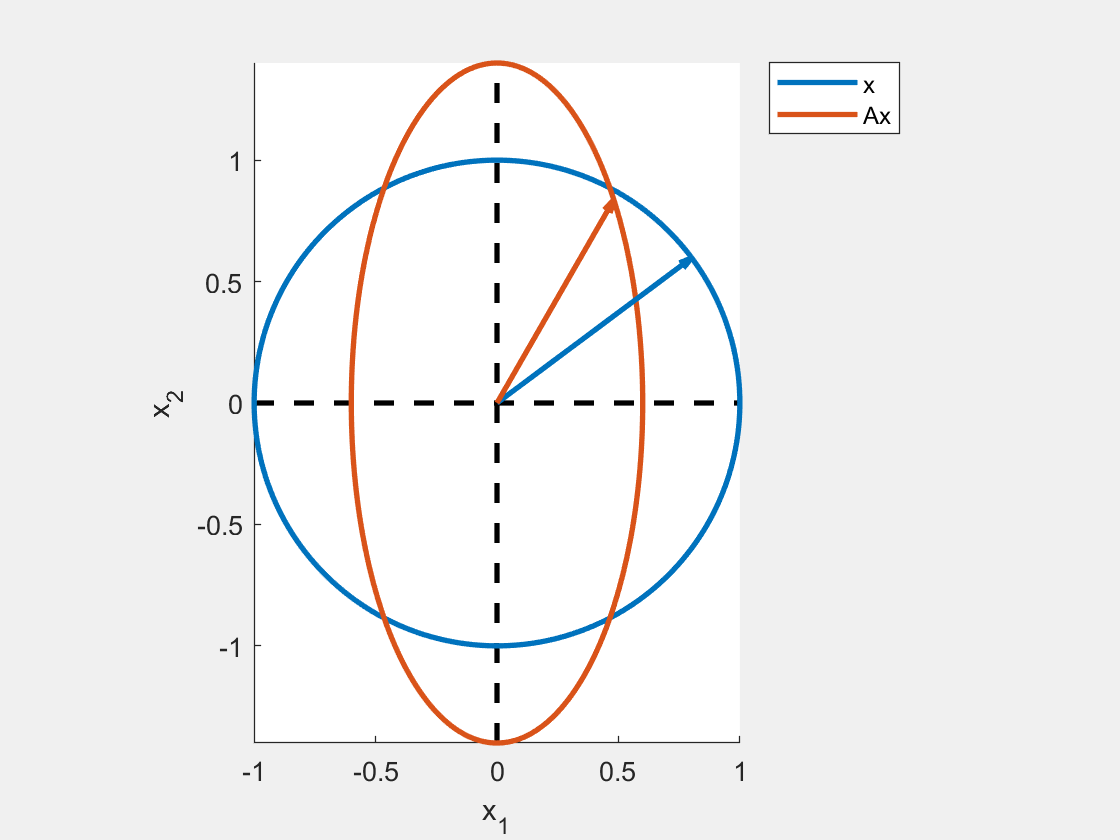

animate_matrix(D, 'e')  % animation #2

As already noted, $D$ has the same eigenvalues as $A$: $3/5$ and $7/5$.  Its eigen*vectors* are quite different however.  In fact, the eigenvectors of $D$ are simply $e_1$ and $e_2$ (the standard basis vectors) as you can easily verify yourself (and which is obvious from the animation).

#### Exercise

Verify (any way you prefer) that the eigenvectors of $D$ are $e_1$ and $e_2$.▫

In fact we can build as many different matrices with the same eigenvalues of $A$ as we like.  We just pick an arbitrary invertible matrix $W = [w_1 | w_2]$ -- containing our desired eigenvectors -- and form the new matrix $B = WDW^{-1}$.  The diagonalisation property now guarantees that $B$ has the same eigenvalues as $D$, and hence, the same eigenvalues as $A$.

For example, we can build a matrix $B$ whose eigenvectors are $w_1 = \left[\matrix{1\cr3}\right]$ and $w_2 = \left[\matrix{1\cr1}\right]$ and having the same eigenvalues as $A$ as follows:

W = [1 1 ; 3 1], B = W*D*inv(W)

W =      1     1
     3     1


$$B = \left(\begin{array}{cc} \frac{9}{5} & -\frac{2}{5}\\ \frac{6}{5} & \frac{1}{5} \end{array}\right)$$

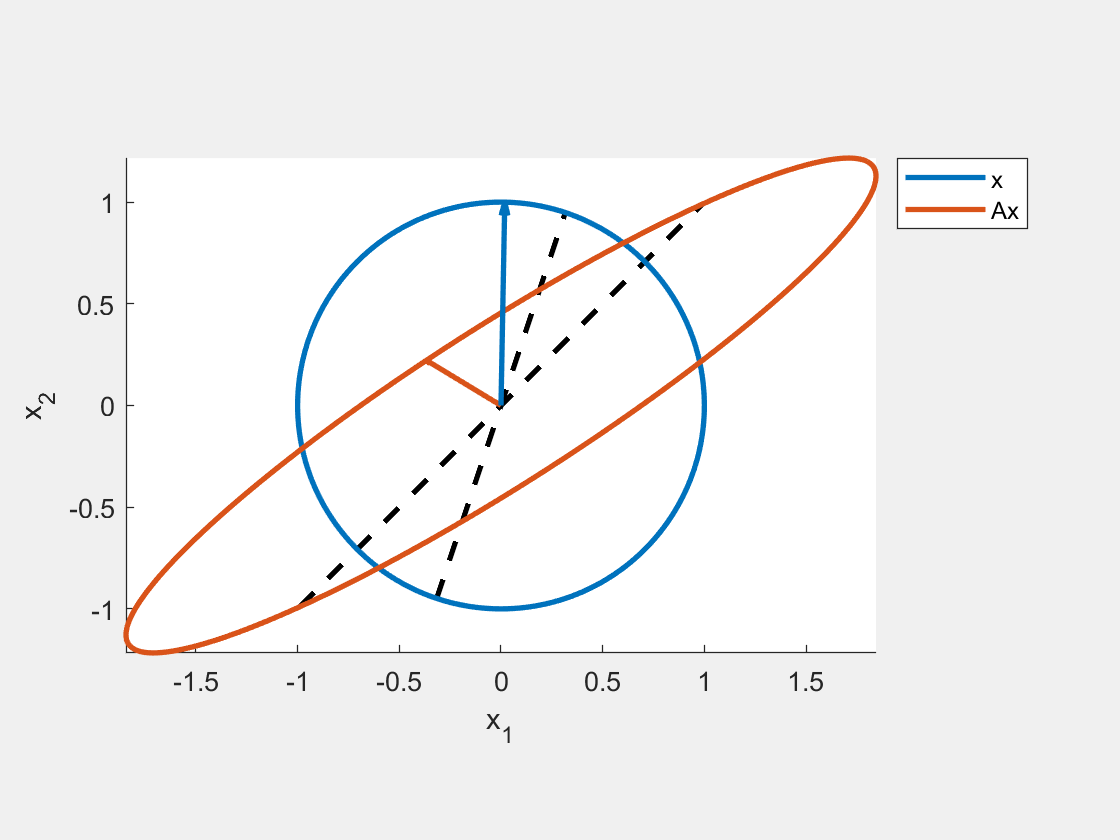

animate_matrix(B, 'e')  % animation #3

#### Exercise

Verify (any way you prefer) that the eigenvectors of $B$ are $w_1$ and $w_2$.▫

### Similar matrices

[Video](https://web.microsoftstream.com/video/9401e0d2-7689-407a-b2c2-48c85701f6e8)

We now have matrices $A$ and $B$ satisfying: $A = VDV^{-1}$ and $B = WDW^{-1}$.  We can relate $A$ and $B$ directly by eliminating the "middle man" $D$.  Rewrite the equation for $A$ as $D = V^{-1} A V$ and substitute in the equation for $B$:

$B = WDW^{-1} = W(V^{-1}AV)W^{-1} = (WV^{-1}) A (VW^{-1}) = (VW^{-1})^{-1} A (VW^{-1}) = P^{-1}AP$, where $P = VW^{-1}$.

Any two matrices $A$ and $B$ that are related by $B = P^{-1}AP$ are called *similar matrices.*

Hence the term "similar" acquires a precise, technical meaning in the sense of the eigenvalue problem.

We see from our derivation that **similar matrices have the same eigenvalues**.  This could also be proved by showing that the characteristic polynomials of $A$ and $B$ coincide.

Being able to diagonalise a matrix, i.e. writing $A = VDV^{-1}$ is extremely useful, but can we be sure that the eigenvector matrix $V$ is invertible?  In the most common case, which is when $A$ has $n$ *distinct* eigenvalues, $\lambda_1 \neq \lambda_2 \neq \cdots \neq \lambda_n$, then yes we can, because:

*Eigenvectors corresponding to distinct eigenvalues are linearly independent.*

## 4.4 Example 3: A "dissimilar matrix"

What would the animation look like if the eigenvalues in our problem were instead $\lambda_1 = -3/5$ and $\lambda_2 = 7/5$ (so, $\lambda_1$ has changed sign) while the eigen*vectors* were the same as $A$'s?  There is no special term for matrices with the same eigenvectors.  But we can certainly create the matrix with the properties we want using the diagonalisation.  We want $A\prime = VD\prime V^{-1}$, where we've used primes on $A\prime$ and $D\prime$ to indicate that their first eigenvalue has changed sign.

Dprime = sym(diag([-3/5, 7/5]))  % sign change for lambda_1

$$Dprime = \left(\begin{array}{cc} -\frac{3}{5} & 0\\ 0 & \frac{7}{5} \end{array}\right)$$

Aprime = V*Dprime*inv(V)  % same V as before

$$Aprime = \left(\begin{array}{cc} \frac{2}{5} & -\frac{1}{2}\\ -2 & \frac{2}{5} \end{array}\right)$$

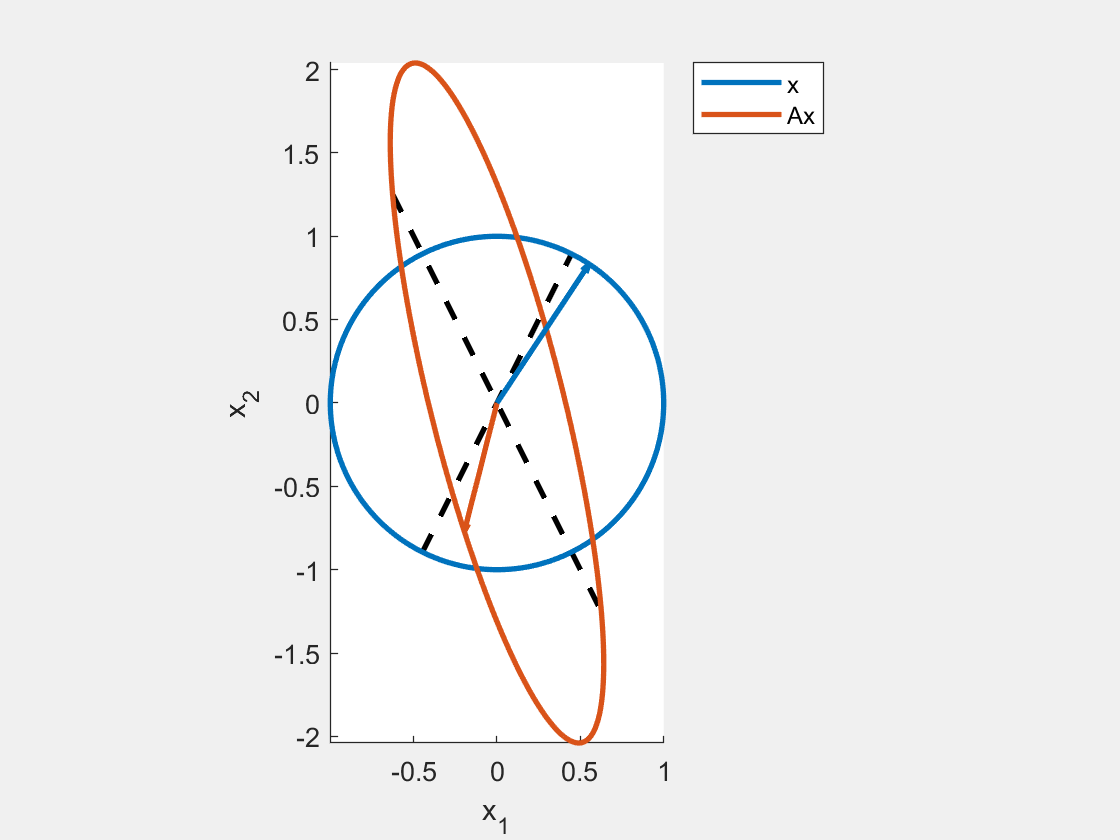

animate_matrix(Aprime, 'e')  % animation #4

As $x$ rotates clockwise, the vector $Ax$ rotates *anti*clockwise.  At the eigenvector $v_1$ (remember, this is the same $v_1$ as for $A$) now the blue and red vectors point in opposite directions, confirming the negative eigenvalue.  At the eigenvector $v_2$ there is no change compared to the animation for $A$.

The observant reader will have noticed that although the eigenvectors are unchanged in this example compared to $A$, and the eigenvalues have the same magnitude as before, the red ellipse is noticeably more eccentric (squished!) in this new example.  Evidently it is *not* the eigenvalues or eigenvectors of $A$ that determine the properties of the ellipse.  Again, we need the concepts from Chapter 5 to shed light on this.

## 4.5 More examples

Must a $2 \times 2$ matrix have precisely 2 eigenvalues?  Let's think about the characteristic polynomial of an arbitrary $2 \times 2$ matrix:

A = sym('a', [2 2])

$$A = \left(\begin{array}{cc} a_{1,1} & a_{1,2}\\ a_{2,1} & a_{2,2} \end{array}\right)$$

P = collect(det(I - lambda*A))

$$P = \left(a_{1,1}\,a_{2,2}-a_{1,2}\,a_{2,1}\right)\,\lambda^{2}+\left(-a_{1,1}-a_{2,2}\right)\,\lambda +1$$

It's a polynomial of degree 2, so it certainly has exactly 2 roots.  So every $2 \times 2$ matrix (in general, $n \times n$ matrix) has exactly 2 (exactly $n$) eigenvalues.  However, be careful not to read too much into this statement!  Any or all of these roots may be equal, meaning we are left with fewer than 2 (fewer than $n$) *distinct* eigenvalues.  Furthermore, some of the roots might well be *complex* numbers, meaning that *a real matrix can have complex eigenvalues*.

### A defective matrix

[Video](https://web.microsoftstream.com/video/15ae9aac-cc36-4a3d-87b9-4d0ad585e9e7)

Here's an example of a $2 \times 2$ matrix with only one distinct eigenvalue.

A = sym([1 0 ; 1 1])

$$A = \left(\begin{array}{cc} 1 & 0\\ 1 & 1 \end{array}\right)$$

H = lambda*I - A

Unrecognized function or variable 'I'.

P = det(H)
d = solve(P == 0)
H1 = subs(H, d(1))
v1 = null(H1)

Its only eigenvalue is $\lambda_1 = 1$ (repeated twice), and its only eigenvector is $v_1 = \left[\matrix{0 \cr 1}\right]$.

There is some special terminology associated with the number of times that an eigenvalue is a root of the characteristic polynomial: it is called the *algebraic multiplicity* of the eigenvalue.  Hence, the *algebraic multiplicity* of the eigenvalue $\lambda_1 = 1$ for this matrix is 2.

There is also a term for the number of linearly independent eigenvectors associated with an eigenvalue: it is called the *geometric multiplicity* of the eigenvalue.  Here, there is just the single eigenvector $v_1$, so the *geometric multiplicity* of the eigenvalue $\lambda_1 = 1$ for this matrix is 1.

The geometric multiplicity of an eigenvalue is always less than or equal to its algebraic multiplicity [Anton, Theorem 5.2.4]

MATLAB respects the algebraic and geometric multiplicity when you call `eig` on a (symbolic) matrix.

[V,D] = eig(A)

$$V = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

Here, the algebraic multiplicity of $\lambda_1 = 1$ is 2, evidenced by the value 1 appearing twice on the diagonal of $D$.  Whereas the geometric multiplicity of $\lambda_1 = 1$ is 1, evidenced by only a single column in $V$ being returned.  Note that this torpedoes any hope we had of writing $A$ as $A = VDV^{-1}$, since clearly $V$ is not invertible this time (it's missing a column!).  This is an important point: **not every matrix is diagonalisable!**

Now, don't panic too much.  Every matrix with *distinct* eigenvalues is diagonalisable [Anton, Theorem 5.2.2].  But many matrices with repeated eigenvalues are also diagonalisable.  In fact, the diagonalisable matrices are precisely those whose algebraic and geometric multiplicities agree for every eigenvalue [Anton, Theorem 5.2.4].

Here, that was not the case, so the matrix $A$ in this example is *not *diagonalisable*, *and hence *not *similar to a diagonal matrix.

There is special terminology for matrices which are not diagonalisable: they are called **defective**.

Here's how it looks in the animation.  The single eigenvalue is clearly evident.

animate_matrix(A, 'e')  % animation #5

### Complex eigenvalues

[Video](https://web.microsoftstream.com/video/a86f5c7b-1f0d-4eeb-b3d2-cef31219d077)

What would the animation look like for a matrix with no real eigenvalues?  Here's an example:

A = sym([3/2 -1 ; 2 -1/2])

$$A = \left(\begin{array}{cc} \frac{3}{2} & -1\\ 2 & -\frac{1}{2} \end{array}\right)$$

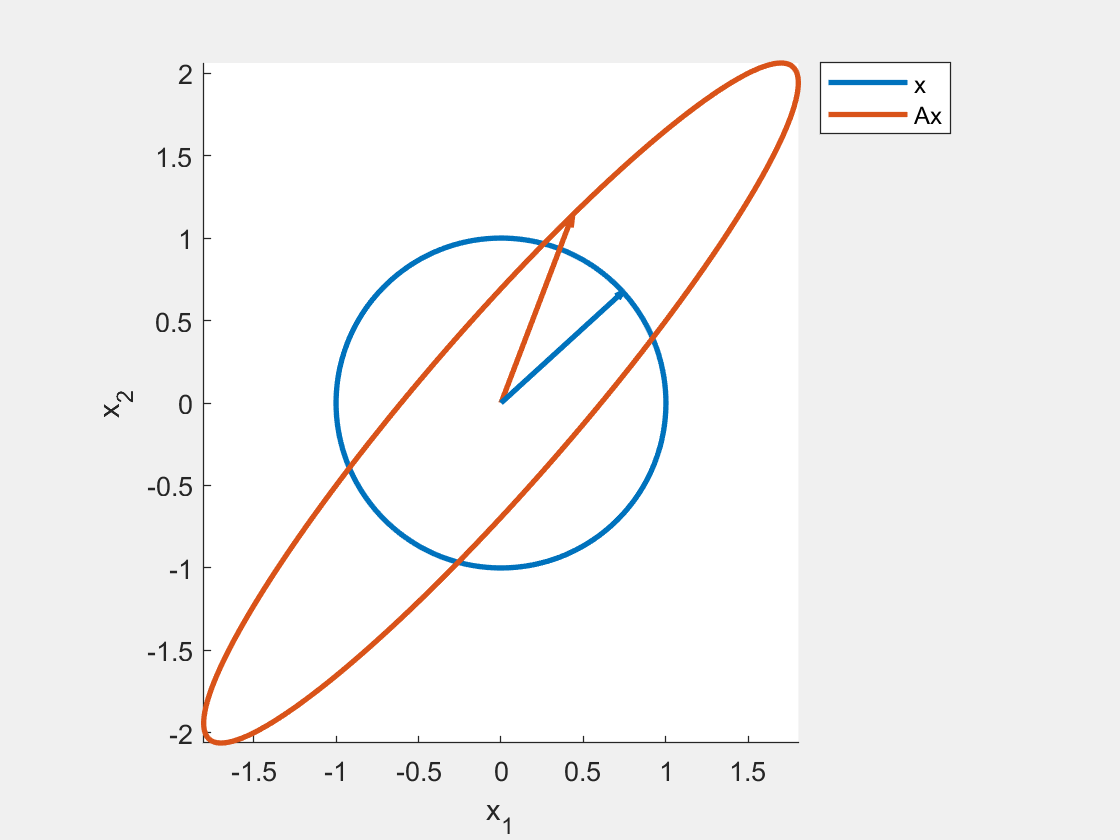

animate_matrix(A, 'e')  % animation #6

This matrix does have *complex* eigenvalues and eigenvectors.  Nothing special changes when calculating these.  The characteristic polynomial has complex roots, and the null spaces of $\lambda I - A$ are hence also complex.

H = lambda*I - A

$$H = \left(\begin{array}{cc} \lambda -\frac{3}{2} & 1\\ -2 & \lambda +\frac{1}{2} \end{array}\right)$$

P = det(H)

$$P = \lambda^{2}-\lambda +\frac{5}{4}$$

d = solve(P == 0)

$$d = \left(\begin{array}{c} \frac{1}{2}-\mathrm{i}\\ \frac{1}{2}+\mathrm{i} \end{array}\right)$$

H1 = subs(H, d(1))

$$H1 = \left(\begin{array}{cc} -1-\mathrm{i} & 1\\ -2 & 1-\mathrm{i} \end{array}\right)$$

v1 = null(H1)

$$v1 = \left(\begin{array}{c} \frac{1}{2}-\frac{1}{2}\,\mathrm{i}\\ 1 \end{array}\right)$$

H2 = subs(H, d(2))

$$H2 = \left(\begin{array}{cc} -1+\mathrm{i} & 1\\ -2 & 1+\mathrm{i} \end{array}\right)$$

v2 = null(H2)

$$v2 = \left(\begin{array}{c} \frac{1}{2}+\frac{1}{2}\,\mathrm{i}\\ 1 \end{array}\right)$$

V = [v1 v2], D = diag(d)

$$V = \left(\begin{array}{cc} \frac{1}{2}-\frac{1}{2}\,\mathrm{i} & \frac{1}{2}+\frac{1}{2}\,\mathrm{i}\\ 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{cc} \frac{1}{2}-\mathrm{i} & 0\\ 0 & \frac{1}{2}+\mathrm{i} \end{array}\right)$$

This matrix has two eigenvalues $\lambda_1 = 1/2-i$ and $\lambda_2 = 1/2+i$, with two associated eigenvectors $v_1 = \left[\matrix{1-i \cr 2}\right]$ and $v_2 = \left[\matrix{1+i \cr 2}\right]$.  It is diagonalisable, but the matrices $V$ and $D$ are both complex.

isequal(A, V*D*inv(V))

ans = logical
   1


Whether complex eigenvalues are *meaningful* in a problem described by real numbers really depends on the application.  For many applications, especially in problems of differential equations, they are of the utmost importance.  In these problems, the real part of an eigenvalue is associated with exponential growth or decay of solutions, whereas the imaginary part is associated with oscillatory behaviour.  We won't delve very much into problems with complex eigenvalues in this unit.

## 4.6 A larger, defective matrix

[Video](https://web.microsoftstream.com/video/7581f354-90e1-45fb-adf9-3fff7e039488)

To paint the picture more clearly around algebraic and geometric multiplicities of eigenvalues, let's consider a $5 \times 5$ matrix.

clear
syms lambda
A = sym([
     1    -2    -5     2    -1
     2    -4   -10     0    -6
     0     5    12    -2     4
     0     0     0     2     0
     1    -5    -9     4    -1
])

$$A = \left(\begin{array}{ccccc} 1 & -2 & -5 & 2 & -1\\ 2 & -4 & -10 & 0 & -6\\ 0 & 5 & 12 & -2 & 4\\ 0 & 0 & 0 & 2 & 0\\ 1 & -5 & -9 & 4 & -1 \end{array}\right)$$

Its characteristic polynomial will be a polynomial of degree 5, which necessarily has 5 roots, but not necessarily distinct.  Let's see.

H = lambda*eye(5) - A; P = det(H)

$$P = \left(\lambda -2\right)\,\left(\lambda^{4}-8\,\lambda^{3}+12\,\lambda^{2}+32\,\lambda -64\right)$$

d = solve(P == 0)  % eigenvalues returned including multiplicities

$$d = \left(\begin{array}{c} -2\\ 2\\ 2\\ 4\\ 4 \end{array}\right)$$

MATLAB returns the five roots of $P$ in a vector, and we can see that there are in fact only 3 distinct eigenvalues: $\lambda_1 = -2$ with algebraic multiplicity 1, $\lambda_2 = 2$ with algebraic multiplicity 2, and $\lambda_3 = 4$ with algebraic multiplicity 2.

For this matrix to be diagonalisable, the *geometric* multiplicities of these eigenvalues must also be 1, 2 and 2 respectively.  Let's see.

v1 = null(subs(H, d(1)))

$$v1 = \left(\begin{array}{c} 0\\ 2\\ -1\\ 0\\ 1 \end{array}\right)$$

The eigenspace associated with $\lambda_1 = -2$ is $\textrm{span}\left\{\left[\matrix{0 \cr 2 \cr -1 \cr 0 \cr 1}\right]\right\}$.  This is a one-dimensional eigenspace.  Hence the geometric multiplicity of the eigenvalue $\lambda_1 = -2$ is 1.

 v2 = null(subs(H, d(2)))

$$v2 = \left(\begin{array}{cc} -1 & 0\\ -2 & -1\\ 1 & 0\\ 0 & -\frac{1}{2}\\ 0 & 1 \end{array}\right)$$

The eigenspace associated with $\lambda_2 = 2$ is $\textrm{span}\left\{\left[\matrix{-1 \cr -2 \cr 1 \cr 0 \cr 0}\right], \left[\matrix{0 \cr -1 \cr 0 \cr -1/2 \cr 1}\right]\right\}$.  This is a two-dimensional eigenspace.  Hence the geometric multiplicity of the eigenvalue $\lambda_2 = 2$ is 2.

 v3 = null(subs(H, d(4)))

$$v3 = \left(\begin{array}{c} \frac{1}{2}\\ 0\\ -\frac{1}{2}\\ 0\\ 1 \end{array}\right)$$

The eigenspace associated with $\lambda_3 = 4$ is $\textrm{span}\left\{\left[\matrix{1/2 \cr 0 \cr -1/2 \cr 0 \cr 1}\right]\right\}$.  This is a one-dimensional eigenspace.  Hence the geometric multiplicity of the eigenvalue $\lambda_3 = 4$ is 1.

#### Exercise

In a (separate) MATLAB editor tab, repeat the process of finding the characteristic polynomial, the eigenvalues, and eigenvectors of this matrix yourself.  Don't refer to back to the example code unless you really get stuck.▫

To summarise, for this matrix, we have the following eigenvalues with their respective algebraic and geometric multiplicities.


$$\matrix{\textrm{Eigenvalue} & \textrm{Algebraic multiplicity} \quad & \textrm{Geometric multiplicity} \cr \lambda_1 = -2 & 1 & 1 \cr \lambda_2 = 2 & 2 & 2 \cr \lambda_3 = 4 & 2 & 1}$$


The algebraic and geometric multiplicity of $\lambda_3 = 4$ do not agree: there is only a one-dimensional eigenspace associated with this eigenvalue (geometric multiplicity = 1), despite it being a double root of the characteristic polynomial (algebraic multiplicity = 2).

Because of this, the matrix is *defective*.  It cannot be diagonalised.  We do not have enough linearly independent eigenvectors to assemble into a basis for $\mathbb{R}^5$.  Bad luck us.

MATLAB agrees, by the way.  Here's its output from `eig` on this matrix.  Notice how there are only 4 linearly independent eigenvectors returned.  (The optional third output `idx` from `eig` is an index vector, which clarifies that the columns of $V$ correspond to the first four diagonal entries in $D$ for this example.)

 [V,D,idx] = eig(A)  % idx is such that A*V == V*D(idx,idx)

$$V = \left(\begin{array}{cccc} 0 & -1 & 0 & \frac{1}{2}\\ 2 & -2 & -1 & 0\\ -1 & 1 & 0 & -\frac{1}{2}\\ 0 & 0 & -\frac{1}{2} & 0\\ 1 & 0 & 1 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccccc} -2 & 0 & 0 & 0 & 0\\ 0 & 2 & 0 & 0 & 0\\ 0 & 0 & 2 & 0 & 0\\ 0 & 0 & 0 & 4 & 0\\ 0 & 0 & 0 & 0 & 4 \end{array}\right)$$

idx =      1     2     3     4


It should be emphasised that most matrices are in fact diagonalisable, so in a sense we were "unlucky" with this example.  Indeed, the smallest perturbation of the matrix in this example would produce a diagonalisable matrix.  Observe:

 B = double(A) + 0.0001*randn(size(A))

B =     1.0001   -2.0001   -5.0001    2.0000   -0.9999
    2.0002   -4.0000   -9.9997   -0.0000   -6.0001
   -0.0002    5.0000   12.0001   -1.9999    4.0001
    0.0001    0.0004   -0.0000    2.0001    0.0002
    1.0000   -4.9997   -8.9999    4.0001   -1.0000


 [V,D] = eig(B)

V =    -0.0000   -0.4089    0.4075   -0.4626    0.2636
   -0.8165   -0.0084   -0.0088   -0.3065   -0.2678
    0.4083    0.4132   -0.4031    0.4625   -0.2635
    0.0001   -0.0001    0.0001    0.3093   -0.3973
   -0.4082   -0.8136    0.8194   -0.6185    0.7947


D =    -1.9999         0         0         0         0
         0    4.0215         0         0         0
         0         0    3.9793         0         0
         0         0         0    1.9993         0
         0         0         0         0    2.0000


The small perturbation has split the repeated eigenvalues into distinct eigenvalues. Only matrices with repeated eigenvalues can possibly be defective.  And even then, many matrices with repeated eigenvalues are actually not defective, they're diagonalisable.  So defective matrices are rare (but for sure they do crop up in certain specialised applications).

## 4.7 Symmetric matrices

[Video](https://web.microsoftstream.com/video/9a54ac6f-0099-447e-a5b6-8f512a6ed967)

When it comes to eigenvalues, the kings of matrices are the symmetric matrices.  Symmetric matrices enjoy a number of extremely important properties that their non-symmetric counterparts do not.  Check out this impressive list:

- Symmetric matrices are always diagonalisable.  This includes symmetric matrices with repeated eigenvalues: they're all always diagonalisable.

- The eigenvalues and eigenvectors of (real) symmetric matrices are always real.

- The eigenspaces of a symmetric matrix are orthogonal.  That is, if $v_1$ and $v_2$ are eigenvectors of a symmetric matrix associated with eigenvalues $\lambda_1$ and $\lambda_2$ respectively, with$\lambda_1 \neq \lambda_2$, then $v_1 \cdot v_2 = 0$.

We will not prove the first two facts, because to do so requires developing the theory of complex vector spaces (in the end, the results come out as real, but you need to detour through complex to show it is so).

The proof of 3 is not difficult, and is one of your exercises for this chapter.

Let's verify these facts for a $5 \times 5$ example.

clear; syms lambda
A = sym([
     3     1    -1     3     1
     1     5     2     1    -2
    -1     2     5    -1     2
     3     1    -1     3     1
     1    -2     2     1     5])

$$A = \left(\begin{array}{ccccc} 3 & 1 & -1 & 3 & 1\\ 1 & 5 & 2 & 1 & -2\\ -1 & 2 & 5 & -1 & 2\\ 3 & 1 & -1 & 3 & 1\\ 1 & -2 & 2 & 1 & 5 \end{array}\right)$$

isequal(A, A')  % A is symmetric

ans = logical
   1


H = lambda*sym(eye(5)) - A; P = det(H)  % usual procedure

$$P = \lambda^{5}-21\,\lambda^{4}+147\,\lambda^{3}-343\,\lambda^{2}$$

 d = solve(P == 0) % all eigenvalues will be real

$$d = \left(\begin{array}{c} 0\\ 0\\ 7\\ 7\\ 7 \end{array}\right)$$

All eigenvalues are real.  The first eigenvalue is $\lambda_1 = 0$.  Note that this means the matrix $0I - A$ has a nontrivial null space.  That is, $A$ is singular.

$\lambda = 0$* is an eigenvalue of *$A$ $\iff$ $A$* is singular*

But singularity is relevant to solving $Ax = b$.  It has no special relevance to the eigenvalue problem $Ax = \lambda x$  The value $\lambda = 0$ is as valid an eigenvalue as any other.

Let's find the associated eigenspace.

 H1 = subs(H, d(1))  % this will just be -A, since d(1) == 0

$$H1 = \left(\begin{array}{ccccc} -3 & -1 & 1 & -3 & -1\\ -1 & -5 & -2 & -1 & 2\\ 1 & -2 & -5 & 1 & -2\\ -3 & -1 & 1 & -3 & -1\\ -1 & 2 & -2 & -1 & -5 \end{array}\right)$$

 V1 = null(H1)

$$V1 = \left(\begin{array}{cc} -1 & -1\\ 0 & 1\\ 0 & -1\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

The eigenvalue $\lambda_1 = 0$ is a double root of $P$.  Hence, the algebraic multiplicity of $\lambda_1$ is 2.

The dimension of the eigenspace associated with $\lambda_1 = 0$ is 2.  Hence, the geometric multiplicity of $\lambda_1$ is 2.

The algebraic multiplicity and geometric multiplicity of $\lambda_1$ are equal.  Since $A$ is symmetric, this was guaranteed.

Now for the second eigenvalue.

H2 = subs(H, d(3))

$$H2 = \left(\begin{array}{ccccc} 4 & -1 & 1 & -3 & -1\\ -1 & 2 & -2 & -1 & 2\\ 1 & -2 & 2 & 1 & -2\\ -3 & -1 & 1 & 4 & -1\\ -1 & 2 & -2 & -1 & 2 \end{array}\right)$$

V2 = null(H2)

$$V2 = \left(\begin{array}{ccc} 0 & 1 & 0\\ 1 & 1 & -1\\ 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

The eigenvalue $\lambda_2 = 7$ is a triple root of $P$.  Hence, the algebraic multiplicity of $\lambda_2$ is 3.

The dimension of the eigenspace associated with $\lambda_2 = 7$ is 3.  Hence, the geometric multiplicity of $\lambda_2$ is 3.

The algebraic multiplicity and geometric multiplicity of $\lambda_2$ are equal.  Since $A$ is symmetric, this was guaranteed.

#### Exercise

In a (separate) MATLAB editor tab, repeat the process of finding the characteristic polynomial, the eigenvalues, and eigenvectors of this matrix yourself.  Don't refer to back to the example code unless you really get stuck.▫

Having found bases for the two eigenspaces, we can verify that these spaces are orthogonal:

V1' * V2  % the usual pair-wise dot products of the basis vectors

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Now here's a clever idea: suppose we use the Gram-Schmidt process to orthonormalise the basis vectors *within *each eigenspace.

[Q1,~] = qr(V1,0), [Q2,~] = qr(V2,0)

$$Q1 = \left(\begin{array}{cc} -\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}\,\sqrt{7}}{14}\\ 0 & \frac{\sqrt{2}\,\sqrt{7}}{7}\\ 0 & -\frac{\sqrt{2}\,\sqrt{7}}{7}\\ \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}\,\sqrt{7}}{14}\\ 0 & \frac{\sqrt{2}\,\sqrt{7}}{7} \end{array}\right)$$

$$Q2 = \left(\begin{array}{ccc} 0 & \frac{\sqrt{2}\,\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{7}}{35}\\ \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{5}}{10} & -\frac{2\,\sqrt{5}\,\sqrt{7}}{35}\\ \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}\,\sqrt{5}}{10} & \frac{2\,\sqrt{5}\,\sqrt{7}}{35}\\ 0 & \frac{\sqrt{2}\,\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{7}}{35}\\ 0 & 0 & \frac{\sqrt{5}\,\sqrt{7}}{7} \end{array}\right)$$

Now we have orthonormal bases for each eigenspace, and the symmetry of $A$ guarantees that the eigenspaces are orthogonal to one other.  In other words, the matrix $Q = [Q1 | Q2]$ will be a full orthonormal eigenbasis for $\mathbb{R}^n$!

Q = [Q1 Q2]  % orthonormal eigenbasis for R^n

$$Q = \left(\begin{array}{ccccc} -\frac{\sqrt{2}}{2} & -\frac{\sqrt{2}\,\sqrt{7}}{14} & 0 & \frac{\sqrt{2}\,\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{7}}{35}\\ 0 & \frac{\sqrt{2}\,\sqrt{7}}{7} & \frac{\sqrt{2}}{2} & \frac{\sqrt{2}\,\sqrt{5}}{10} & -\frac{2\,\sqrt{5}\,\sqrt{7}}{35}\\ 0 & -\frac{\sqrt{2}\,\sqrt{7}}{7} & \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}\,\sqrt{5}}{10} & \frac{2\,\sqrt{5}\,\sqrt{7}}{35}\\ \frac{\sqrt{2}}{2} & -\frac{\sqrt{2}\,\sqrt{7}}{14} & 0 & \frac{\sqrt{2}\,\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{7}}{35}\\ 0 & \frac{\sqrt{2}\,\sqrt{7}}{7} & 0 & 0 & \frac{\sqrt{5}\,\sqrt{7}}{7} \end{array}\right)$$

The matrix $Q$ is an example of an **orthogonal matrix**: a square matrix whose columns form an orthonormal basis for $\mathbb{R}^n$.  (The terminology is weird, you would expect it to be called an "orthonormal matrix", but we're stuck with the terminology we have.)

Hence, $Q$ satisfies* both* $Q^T Q = I$ (because its columns are orthonormal) *and* $QQ^T = I$ (because it's an orthogonal projector onto all of $\mathbb{R}^n$).  $Q^T$ is thus the *inverse* of $Q$.  Very special indeed!

*An ****orthogonal matrix*** $Q$* satisfies *$Q^{-1} = Q^T$*.*

A valuable property of orthogonal matrices is that multiplication by such a matrix leaves a vector's length unchanged: $\|Qx\| = \|x\|$ for any $x$ if $Q^{-1} = Q^T$.  Hence, as linear transformations, orthogonal matrices are always rotations and/or reflections -- there is no scaling associated with the transformation.

We emphasise again that only square matrices can be orthogonal.  The terminology does not apply to a rectangular matrix satisfying $Q^TQ = I$ but not $QQ^T = I$.

Thus every $n \times n$ symmetric matrix carries with it the "perfect choice" of orthonormal basis for $\mathbb{R}^n$: its own orthonormal eigenbasis.  Using this basis for $\mathbb{R}^n$ makes solving problems with this matrix $A$ much easier, because with respect to this basis, $A$ acts just like a diagonal matrix.

Here we exhibit the **orthogonal diagonalisation** $D = Q^TAQ$.  Notice that we need no matrix inverses at all: instead of $Q^{-1}$ we can use $Q^T$.  Symmetric matrices are so nice to work with.

Q'*A*Q  % diagonal matrix of eigenvalues

$$ans = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 7 & 0 & 0\\ 0 & 0 & 0 & 7 & 0\\ 0 & 0 & 0 & 0 & 7 \end{array}\right)$$

#### Exercise

In a (separate) MATLAB editor tab, repeat the process of finding the orthogonal diagonalisation of $A$.  Don't refer to back to the example code unless you really get stuck.▫

### Symmetric positive definite matrices

A subclass of symmetric matrices are the *Symmetric Positive Definite (SPD)* matrices.  SPD matrices are precisely those which are symmetric *and* whose eigenvalues are all positive.  SPD matrices carry orthonormal eigenbases with them, as does every symmetric matrix, but they are additionally always nonsingular (since zero can't be an eigenvalue), and they admit Cholesky decompositions $A = LL^T$.  What more could you ask for!

Our example above was not SPD, since it had zero as an eigenvalue (instead this matrix would be described as positive *semi*definite).  An example of an SPD matrix is $A^TA$ for any (rectangular) matrix $A$ with full column rank.

### Diagonalisation summary

[Video](https://web.microsoftstream.com/video/c3c97b07-3f22-48b6-8d10-c2572dc5fa2c)

We supposed above that the matrix $V$ is invertible.  If so, it has $n$ linearly independent columns (the eigenvectors), meaning that the eigenvectors form a basis for $\mathbb{R}^n$.  This is a very special basis, particular to the matrix $A$, called the **eigenbasis**.  If we use this special eigenbasis as our basis for $\mathbb{R}^n$, then multiplication of $A$ by any vector acts just like a diagonal scaling by $D$.  Compare:

Using the standard basis for $\mathbb{R}^n$:  We have a vector $x$, which we multiply by $A$ to get $b$.  $Ax = b$.

Using $A$'s eigenbasis:  We represent $x$ by $x = Vc$ for some coordinate vector $c$.  And we represent $b$ by $b = Vk$ for some coordinate vector $k$.  Then


$$Ax = b$$



$$AVc = Vk$$



$$V^{-1}AVc = k$$



$$Dc = k$$


*With respect to the eigenbasis, a linear transformation from *$\mathbb{R}^n$* to *$\mathbb{R}^n$* is represented by a diagonal matrix.*

## 4.8 Matrix functions

[Video](https://web.microsoftstream.com/video/b55c0fb6-13c6-44fe-a1f6-79290cc4d4c4)

Let's summarise the key points about matrix diagonalisation.

- If $A \in \mathbb{R}^{n \times n}$ is diagonalisable (i.e. if it's not defective) then we can write $A = VDV^{-1}$, where $D = \textrm{diag}(\lambda_1, \ldots \lambda_n)$ is a diagonal matrix of $A$'s eigenvalues, and the columns of $V = [v_1 | \ldots | v_n]$ are the corresponding eigenvectors, which together form a basis for $\mathbb{R}^n$.  Equally, we can write $V^{-1}AV = D$.

- If $A$ is *symmetric*, the eigenvalues will be real, the eigenbasis can be made orthonormal, and we can write $A = QDQ^T$ and $Q^TAQ = D$.

- If $A$ is *symmetric positive definite*, the eigenvalues will be positive, the eigenbasis can be made orthonormal, and we can write $A = QDQ^T$ and $Q^TAQ = D$, where all diagonal entries of $D$ are positive.

An important application of diagonalisation is in computing *matrix functions*; that is, evaluating $f(A)$ where $f$ is some analytic function and $A$ is a square $n \times n$ matrix.

### Powers

Let's start with matrix powers: how can we calculate $A^k$ for some integer power $k$?  One answer, is just repeatedly multiply $A$ by itself $k$ times.  But that's inefficient, and it doesn't answer the general question of what is $A^k$ for *arbitrary *integer $k$.  A better idea, is to notice that if $A = VDV^{-1}$, then


$$A^2 = A A = VDV^{-1} VDV^{-1} = VD^2V^{-1}$$



$$A^3 = A^2 A = VD^2V^{-1} VDV^{-1} = VD^3V^{-1}$$


and so on.  In general then,


$$A^k = VD^kV^{-1}$$


So we transfer the problem of finding the $k$th power from $A$ onto the diagonal matrix $D$.  But powers of diagonal matrices are trivial: if $D = \textrm{diag}(\lambda_1, \ldots, \lambda_n)$ then $D^k = \textrm{diag}({\lambda_1}^k, \ldots, {\lambda_n}^k)$.

How clever!  Let's give it a try.  We'll find the $k$th power of

A = sym([1 -1/5 ; -4/5 1])

$$A = \left(\begin{array}{cc} 1 & -\frac{1}{5}\\ -\frac{4}{5} & 1 \end{array}\right)$$

We start by diagonalising $A$.  This was our first example in the chapter.  We'll let MATLAB do the work for us this time.

[V,D] = eig(A); V, d = diag(D)

$$V = \left(\begin{array}{cc} \frac{1}{2} & -\frac{1}{2}\\ 1 & 1 \end{array}\right)$$

$$d = \left(\begin{array}{c} \frac{3}{5}\\ \frac{7}{5} \end{array}\right)$$

The $k$th power of $D$ is just the diagonal matrix of $k$th powers of the eigenvalues.

syms k
D_to_k = diag(d.^k)

$$D\_to\_k = \left(\begin{array}{cc} {\left(\frac{3}{5}\right)}^{k} & 0\\ 0 & {\left(\frac{7}{5}\right)}^{k} \end{array}\right)$$

The $k$th power of $A$ is $VD^kV^{-1}$.

A_to_k = V*D_to_k*inv(V)

$$A\_to\_k = \left(\begin{array}{cc} \frac{{\left(\frac{3}{5}\right)}^{k}}{2}+\frac{{\left(\frac{7}{5}\right)}^{k}}{2} & \frac{{\left(\frac{3}{5}\right)}^{k}}{4}-\frac{{\left(\frac{7}{5}\right)}^{k}}{4}\\ {\left(\frac{3}{5}\right)}^{k}-{\left(\frac{7}{5}\right)}^{k} & \frac{{\left(\frac{3}{5}\right)}^{k}}{2}+\frac{{\left(\frac{7}{5}\right)}^{k}}{2} \end{array}\right)$$

Voila!  Here's $A^7$ for example:

A_to_7 = subs(A_to_k, 7)

$$A\_to\_7 = \left(\begin{array}{cc} \frac{82573}{15625} & -\frac{205339}{78125}\\ -\frac{821356}{78125} & \frac{82573}{15625} \end{array}\right)$$

isequal(A_to_7, A^7)

ans = logical
   1


#### Exercise

In a (separate) MATLAB editor tab, repeat the process of finding the general matrix power $A^k$.  Don't refer to back to the example code unless you really get stuck.▫

### Polynomials

If we can evaluate matrix powers, the next step up is matrix *polynomials*.  Let $p(t) = c_0 + c_1t + c_2t^2 + \ldots c_k t^k$.  Then

 $p(A) = c_0I + c_1A + c_2A^2 + \ldots c_k A^k \\ p(A) = c_0VV^{-1} + c_1VDV^{-1} + c_2VD^2V^{-1} + \ldots c_k VD^kV^{-1} \\ p(A) = V( c_0I + c_1D + c_2D^2 + \ldots c_k D^k)V^{-1} \\ p(A) = V\, p(D) V^{-1}$.

and $p(D)$ is again trivial: it's just the diagonal matrix of the polynomial evaluated at the eigenvalues: $p(D) = \textrm{diag}\left(p(\lambda_1), \ldots p(\lambda_n)\right)$.

Quick example: let's calculate $4I - 5A + 6A^2 - 7A^3 + A^{11}$.

4*eye(2) - 5*A + 6*A^2 - 7*A^3 + A^11  % the hard way!

$$ans = \left(\begin{array}{cc} \frac{154781639}{9765625} & -\frac{346631149}{48828125}\\ -\frac{1386524596}{48828125} & \frac{154781639}{9765625} \end{array}\right)$$

V * diag(4 - 5*d + 6*d.^2 - 7*d.^3 + d.^11) * inv(V) % the easy way!

$$ans = \left(\begin{array}{cc} \frac{154781639}{9765625} & -\frac{346631149}{48828125}\\ -\frac{1386524596}{48828125} & \frac{154781639}{9765625} \end{array}\right)$$

### **Analytic functions**

An analytic function $f$ can be represented by its Taylor series, $f(t) = c_0 + c_1t + c_2t^2 + \ldots c_k t^k + \ldots$.  The same trick we used for polynomials works here too!


$$f(A) = c_0I + c_1A + c_2A^2 + \ldots c_k A^k + \ldots \\ f(A) = c_0VV^{-1} + c_1VDV^{-1} + c_2VD^2V^{-1} + \ldots c_k  VD^kV^{-1} + \ldots \\ f(A) = V( c_0I + c_1D + c_2D^2 + \ldots c_k D^k + \ldots)V^{-1} \\ f(A) = V\, f(D) V^{-1}$$


and $f(D) = \textrm{diag}\left(f(\lambda_1), \ldots f(\lambda_n)\right)$.

For example, we can calculate the matrix exponential $\exp(tA)$ for our little example.

syms t
exp_tA = V * diag(exp(d*t)) * inv(V)

$$exp\_tA = \left(\begin{array}{cc} \frac{{\mathrm{e}}^{\frac{3\,t}{5}}}{2}+\frac{{\mathrm{e}}^{\frac{7\,t}{5}}}{2} & \frac{{\mathrm{e}}^{\frac{3\,t}{5}}}{4}-\frac{{\mathrm{e}}^{\frac{7\,t}{5}}}{4}\\ {\mathrm{e}}^{\frac{3\,t}{5}}-{\mathrm{e}}^{\frac{7\,t}{5}} & \frac{{\mathrm{e}}^{\frac{3\,t}{5}}}{2}+\frac{{\mathrm{e}}^{\frac{7\,t}{5}}}{2} \end{array}\right)$$

#### Exercise

In a (separate) MATLAB editor tab, repeat the process of finding the matrix exponential $\exp(tA)$.  Don't refer to back to the example code unless you really get stuck.▫

The matrix exponential $\exp(tA)$ is one of the most important matrix functions, because it satisfies the key property of calculus that $\frac{\textrm{d}}{\textrm{d}t} \exp(tA) = A \exp(tA)$.  Hence the vector differential equation $y\prime(t) = Ay(t)$ where $y(t) \in \mathbb{R}^n$ and $A \in \mathbb{R}^{n \times n}$ has the solution $y(t) = \exp(tA) c$ for arbitrary vector $c \in \mathbb{R}^n$.  For example, the initial value problem


$$y_1\prime(t) = y_1(t) - y_2(t)/5$$



$$y_2\prime(t) = -4y_1(t)/5 + y_2(t)$$


with $y_1(0) = y_2(0) = 1$

can be written in vector form as 

$\left[\matrix{y_1\prime(t) \cr y_2\prime(t)}\right] = \left[\matrix{1 & -1/5 \cr -4/5 & 1}\right] \left[\matrix{y_1(t) \cr y_2(t)}\right]$ with  $\left[\matrix{y_1(0) \cr y_2(0)}\right] = \left[\matrix{1 \cr 1}\right]$,

or compactly as

$y\prime(t) = Ay(t)$ with $y(0) = [1,1]^T$.

The solution is therefore

y(t) = exp_tA * [1;1]

$$y(t) = \left(\begin{array}{c} \frac{3\,{\mathrm{e}}^{\frac{3\,t}{5}}}{4}+\frac{{\mathrm{e}}^{\frac{7\,t}{5}}}{4}\\ \frac{3\,{\mathrm{e}}^{\frac{3\,t}{5}}}{2}-\frac{{\mathrm{e}}^{\frac{7\,t}{5}}}{2} \end{array}\right)$$

isequal(diff(y), A*y)

ans = logical
   1


In this section we again assumed that $A$ was diagonalisable.  Matrix functions are still defined on defective (i.e. non-diagonalisable) matrices, but it takes more work to build up the theory.  If $A$ is symmetric, then diagonalisation (indeed, *orthogonal* diagonalisation) is guaranteed, so there is nothing further to worry about.

## **4.9 The Cayley-Hamilton theorem**

[Video](https://web.microsoftstream.com/video/b784abef-8cde-49f8-b6de-7da2e359d824)

Here's an interesting question: what is the value of $P(A)$, where the polynomial $P$ is $A$'s own characteristic polynomial?

Well, assuming $A$ is diagonalisable, $A = VDV^{-1}$, we just find as usual $P(A) = V\, P(D) V^{-1}$.

But what is $P(D)$?  It's the diagonal matrix formed by substituting the eigenvalues $\lambda_i$ of $A$ into $P$.  But $P(\lambda_i) = 0$ for each eigenvalue (that's what the characteristic polynomial is *for*!).

Hence we conclude that for any diagonalisable matrix $A$, with characteristic polynomial $P$, that $P(A) = 0$.  In fact, this result is true for *all* matrices, diagonalisable or not, but it's harder to prove in the general case.  The result is known as the *Cayley-Hamilton theorem*:

*If *$A$* is a square matrix, with characteristic polynomial *$P$*, then *$P(A) = 0$*.*

We can confirm this for our little example:

A, P = charpoly(A, 'lambda') % let MATLAB do the work this time

$$A = \left(\begin{array}{cc} 1 & -\frac{1}{5}\\ -\frac{4}{5} & 1 \end{array}\right)$$

$$P = \lambda^{2}-2\,\lambda +\frac{21}{25}$$

A^2 - 2*A + 21/25*eye(2)  % we'll just write out P(A) by hand

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

We see that indeed $P(A) = 0$.

#### Exercise

In a (separate) MATLAB editor tab, repeat the process of verifying that the Cayley-Hamilton theorem is satisfied for this matrix $A$.  Don't refer to back to the example code unless you really get stuck.▫

## **4.10 Summary**

- **Eigenvalues** $\lambda_i$ and corresponding **eigenvectors** $v_i$ of $A \in \mathbb{R}^{n \times n}$ satisfy $Av_i = \lambda_i v_i$.

-     In matrix form, this reads $AV = VD$, where $V$ has the eigenvectors as its columns, and $D$ has the eigenvalues as its diagonal entries (with zeros elsewhere).

- The monic polynomial defined by $P(\lambda) = \det(\lambda I - A)$ is called the **characteristic polynomial** of $A \in \mathbb{R}^{n \times n}$.  Its roots $\lambda_i$ are the eigenvalues of $A$.

-     The **algebraic multiplicity** of $\lambda_i$ is the number of times $\lambda_i$ is a root of $P(\lambda)$.

-     The **geometric multiplicity** of $\lambda_i$ is $\textrm{nullity}(\lambda_i I - A)$ (i.e. the dimension of the null space of $\lambda_i I - A$).

-     $A$ satisfies its own characteristic equation: $P(A) = 0$.  This is the **Cayley-Hamilton theorem**.

- If $A \in \mathbb{R}^{n \times n}$ has $n$ linearly independent eigenvectors $v_i$, then $V$ is invertible, and $A = VDV^{-1}$ or equally, $V^{-1}AV = D$.  We say that $A$ is **diagonalisable**.

-     The conditions for $A$ to be diagonalisable are that the algebraic and geometric multiplicity agree for each eigenvalue.

-     If $A$ is not diagonalisable, it is called **defective**.  The algebraic and geometric multiplicity do not agree for at least one eigenvalue.  It has fewer than $n$ linearly independent eigenvectors.

- Every real symmetric matrix $A$ has real eigenvalues and is **orthogonally diagonalisable**: $A = QDQ^T$ or equally, $Q^TAQ = D$.

-     The matrix $Q$ of orthonormal eigenvectors satisfies $Q^{-1} = Q^T$ and is called an **orthogonal matrix**.

- If $A$ is diagonalisable, then we may define $f(A)$, where $f$ is an analytic function, by $f(A) = V\,\textrm{diag}\left(f(\lambda_1), \ldots f(\lambda_n)\right)V^{-1}$.